# **Musical Tuner Pitch Recognition**

The program will take an audio input sound from a guitar (via speaker) and tell information about the

pitch it detects (whether the note played is in tune or not). 

## 1) Detecting the audio signal

#### Recording a guitar sound from a microphone.

First of all, create an `audiorecorder` object with the desired properties.

For a CD-quality audio in stereo, define these properties : 

sampling frequency (`Fs`), 

number of bits per sample (`nBits`),

 number of channels (`nChannels`),

 input device identifier (`ID`).

Collect a 2 second sample of guitar playing with your microphone.

`Start playing.`

`End of Recording.`

#### Create a WAVE (`.wav`) file in the current folder.

- we will create a **.wav** file for each guitar string separately.

- `And then we use ``audiowrite `inbuilt command which writes a matrix of audio data, `y`, with sample rate `Fs` to a file called `filename.`

We have already recorded multiple files named as

***TUNED STRING SOUNDS:***

***Elo.wav,***

***A.wav ***

***D.wav***

***G.wav ***

***B.wav  ***

***Ehi.wav***

***UNTUNED STRING SOUNDS:***

***uElo.wav,***

***uA.wav ***

***uD.wav***

***uG.wav ***

***uB.wav  ***

***uEhi.wav***

*These files are stored in ****same zip folder ***already by following the above steps, and we are using it as our sample sounds. 

#### **Read Complete Audio File**

Reading from .wav files (Read the data back into MATLAB using `audioread`*.*)

-  We will use *audio read* inbuit command which reads data from the file named `filename`, and returns sampled data, `y`, and a sample rate for that data, `Fs`.

Here we are storing open string guitar sounds (both untuned and tuned strings) into a cell array and taking a random element from it for the sake of detecting the pitch of a random note

Fs = 44100;
% tuned guitar strings
[audioData1] = audioread('Elo.wav');
[audioData2] = audioread('A.wav');
[audioData3] = audioread('D.wav');
[audioData4] = audioread('G.wav');
[audioData5] = audioread('B.wav');
[audioData6] = audioread('Ehi.wav');
% untuned guitar strings
[audioData7] = audioread('uElo.wav');
[audioData8] = audioread('uA.wav');
[audioData9] = audioread('uD.wav');
[audioData10] = audioread('uG.wav');
[audioData11] = audioread('uB.wav');
[audioData12] = audioread('uEhi.wav');

audioDataList = {audioData1, audioData2, audioData3, audioData4, audioData5, audioData6, audioData7, audioData8, audioData9, audioData10, audioData11, audioData12};

randomIndex = randi([1,12],1,1); %Randomly take any one file from the list .

audioData = audioDataList{randomIndex};

#### Play back the recording.

sound function plays sound from speaker

% audioData = audioread('Elo.wav');  % uncomment to check specific strings
sound(audioData, Fs);

#### Plot original signal in Time domain

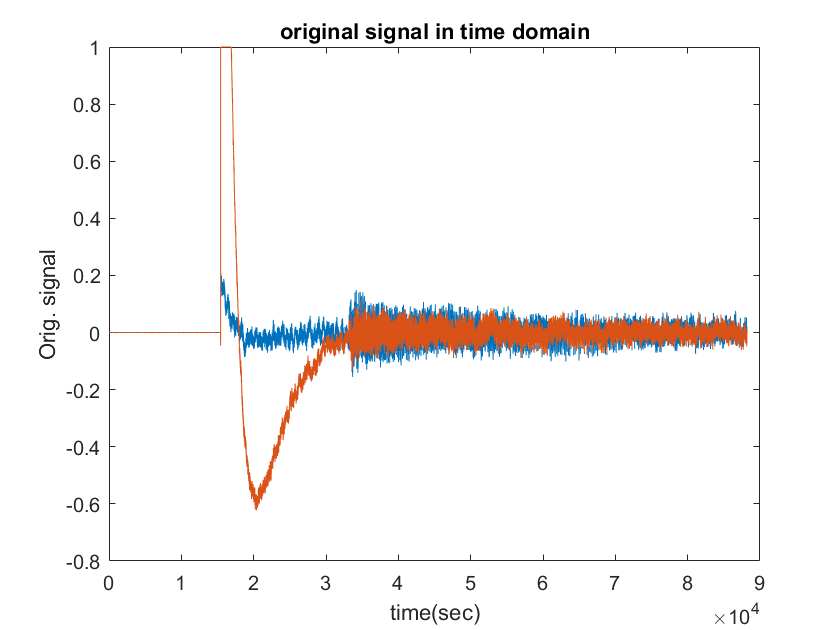

N = length(audioData);
t=0:1:N-1;
plot(t,audioData)
ylabel('Orig. signal');
xlabel('time(sec)');
title('original signal in time domain')

#### Converting original signal to frequency domain

use nextpow2 inbuilt function,

`P = nextpow2(`[`A`](https://in.mathworks.com/help/matlab/ref/nextpow2.html#btswm2v-1-A)`)` returns the exponents for the smallest powers of two that satisfy


$$2^p\ge |A|$$


for each element in `A`. By convention, `nextpow2(0)` returns zero.

You can use `nextpow2` to pad the signal you pass to `fft`. Doing so can speed 

up the computation of the FFT when the signal length is not an exact power of 2.

N = length(audioData); % Original sample length.
n = pow2(nextpow2(N)); % Transforming the length so that the number of 
% samples is a power of 2. This can make the transform computation 
% significantly faster,particularly for sample sizes with large prime 
% factors.
y = fft(audioData, n);

#### Plot original signal in frequency domain

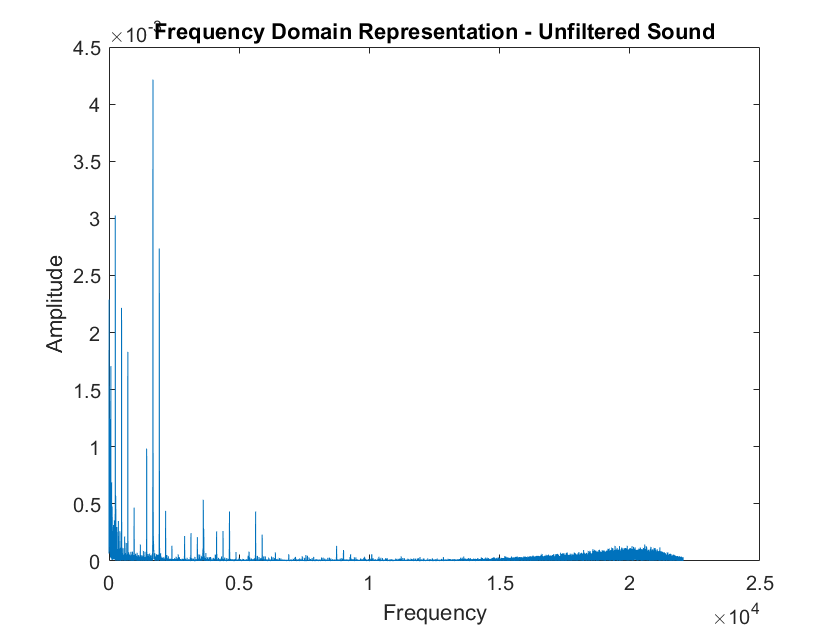


f = (0:n-1)*(Fs/n);
amplitude = abs(y)/n;
plot(f(1:floor(n/2)),amplitude(1:floor(n/2)));
title('Frequency Domain Representation - Unfiltered Sound')
xlabel('Frequency')
ylabel('Amplitude')

## 2) Applying a low pass filter to get rid of the noise

### Applying low pass butter worth filter

- we will use ***butte*****r** which  returns the transfer function coefficients of an `n`th-order lowpass digital Butterworth filter with normalized cutoff frequency `Wn`.

- and before doing that we need to specify the order of the filter

- we then use ***filter*** command which  filters the input data `x` using a transfer function which is rational defined by the numerator and denominator coefficients `b` and `a`.

order = 7;
[b,a] = butter(order,1000/(Fs/2),'low');
filtered_sound = filter(b,a,audioData);

### Listening sound of filtered signal

now by using sound function we can hear the filtered sound 

sound(filtered_sound,Fs);

### Plotting filtered signal in time domain

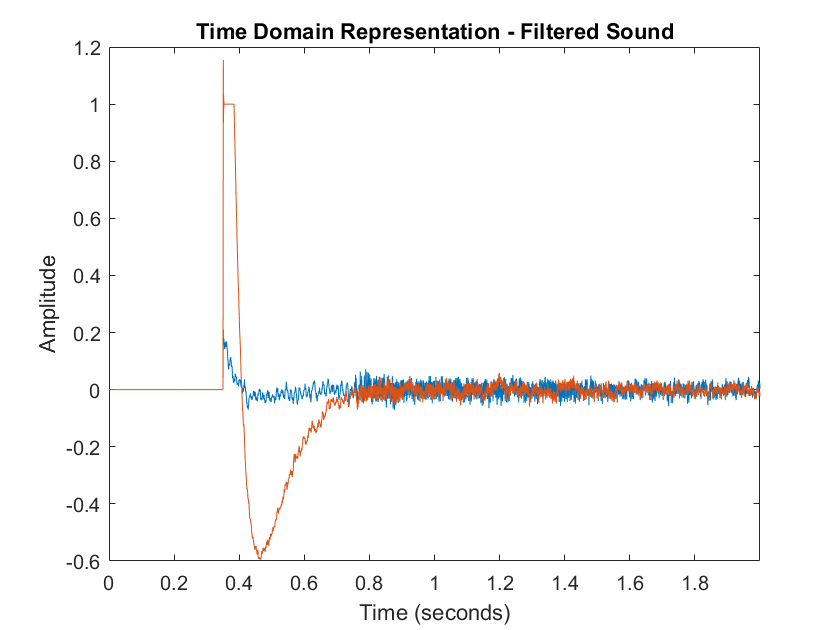

sample_period = 1/Fs;
t1 = (0:sample_period:(length(filtered_sound)-1)/Fs);
plot(t1,filtered_sound)
title('Time Domain Representation - Filtered Sound')
xlabel('Time (seconds)')
ylabel('Amplitude')
xlim([0 t1(end)])

### Converting Filtered signal to frequency domain

use nextpow2 inbuilt function,

`P = nextpow2(`[`A`](https://in.mathworks.com/help/matlab/ref/nextpow2.html#btswm2v-1-A)`)` returns the exponents for the smallest powers of two that satisfy


$$2^p\ge |A|$$


for each element in `A`. By convention, `nextpow2(0)` returns zero.

You can use `nextpow2` to pad the signal you pass to fft. Doing so can speed up the computation of the FFT when the signal length is not an exact power of 2.

N = length(audioData); % Original sample length.
n1 = pow2(nextpow2(N)); % Transforming the length so that the number of 
% samples is a power of 2. This can make the transform computation 
% significantly faster,particularly for sample sizes with large prime 
% factors.

#### Finding fft of the filtered sound

y = fft(filtered_sound, n1);

#### Plotting filtered signal in frequency domain

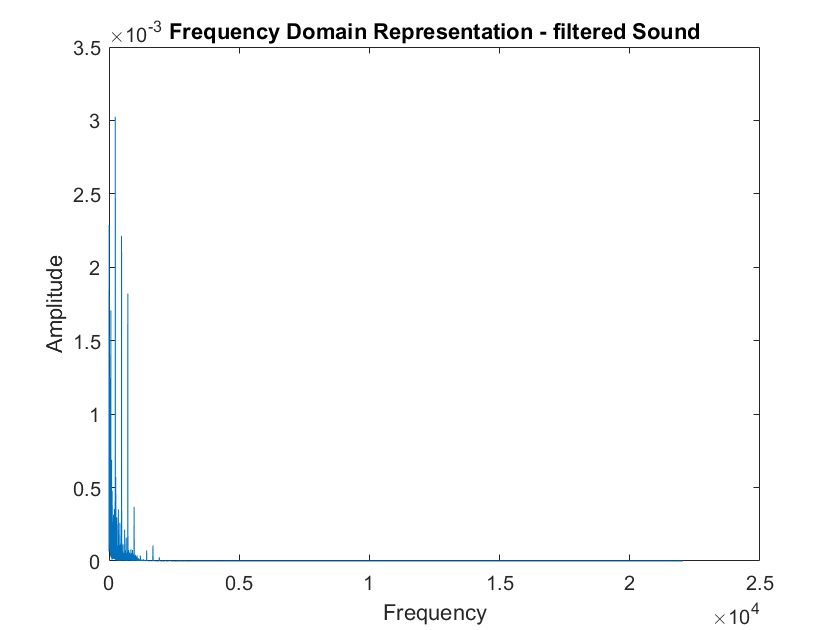

f = (0:n1-1)*(Fs/n1);
amplitude = abs(y)/n1;
plot(f(1:floor(n1/2)),amplitude(1:floor(n1/2)))
title('Frequency Domain Representation - filtered Sound')
xlabel('Frequency')
ylabel('Amplitude')

## 3) Identifying the note

  Here by using *max *inbuit function we will find at what frequency our amplitude of the filtered signal is maximum. and we will use that frequency for the next step.

[Y_index, X_index] = max(amplitude(1:floor(n1/2)));
frequency_at_Max_amplitude = f(X_index);

- firstly we know the fundamental frequencies of each note

- and the *frequency_at_Max_amplitude* what we got will be approximately equal to the multiples of fundamental frequency

- by using ***rem*** function we will find the reminder of *frequency_at_Max_amplitude* and fundamental frequency

- if the reminder is approximately or near to zero for a paticular fundamental frequency we will display that note is in tune

#### *open guitar strings  *           * fundamental frequency(HZ) *

**E low                                                        82.4**

**A                                                               110.0**

**D                                                               146.8**

**G                                                               196.0**

**B                                                               246.9**

**E high                                                       329.6**

if (rem(frequency_at_Max_amplitude, 82.4) < 1.3 && rem(frequency_at_Max_amplitude, 82.4) > 0.2)
    disp("'E' low string note is in tune")
elseif (rem(frequency_at_Max_amplitude, 110.0) < 0.5 && rem(frequency_at_Max_amplitude, 110.0) > 0)
    disp("'A' string note is in tune ")
elseif (rem(frequency_at_Max_amplitude, 146) < 1.5 && rem(frequency_at_Max_amplitude, 146) > 0)
    disp("'D' string note is in tune")
elseif (rem(frequency_at_Max_amplitude, 196.0) < 1 && rem(frequency_at_Max_amplitude, 196.0) > 0)
    disp("'G' string note is in tune")
elseif (rem(frequency_at_Max_amplitude, 246.9) < 0.2 && rem(frequency_at_Max_amplitude, 246.9) > 0)
    disp("'B' string note is in tune")
elseif (rem(frequency_at_Max_amplitude, 329.6) < 0.5 && rem(frequency_at_Max_amplitude, 329.6) > 0)
    disp("'E' high string note is in tune")
else
    disp("the note played is not in tune") % if it fails the above comparisons, it means note played is not in tune
end

the note played is not in tune


## Conclusion:-

- *From this project we are able to implement fft and low pass filtering by using butter worth filter.*

- *We are able to detect the pitch of the note that is being played by using the above techniques and then using the fact that harmonics that are appearing in frequency spectrum are muliples of the fundamental frequency of the required note.*

- *We have provided the ranges for the errors that occured due to disturbances/noise  in the original recorded sounds.*

- *We concluded that the guitar is tuned if the harmonics are close to the multiples of the fundamental frequency that lie within these error ranges of the givien 6 notes of the open strings of the guitar or else the guitar is untuned.*